# **Modbus RTU Multi-Node Loopback**

This example demonstrates how one Modbus RTU Client and three Modbus RTU Servers communicate.

All the Modbus nodes are in the same system and on two different serial interface channels. With this setup, the Modbus RTU Client is on channel one and the Modbus RTU Servers are on channel two (for IO503/IO505) or on channel 3 (for IO504). The server setup block is configured to simulate three server nodes.

The Simulink model features the Modbus RTU blocks from the [speedgoatlib_mbrtu](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_landing) library.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least two unused serial interface channels

- "Runtime License File" for Modbus RTU Client (if purchased) and Server(s). Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

- IO50X:

-     Connector cable from the I/O module to the terminal boards

-     50-pin terminal board with jumper wires

- IO581:

-     Connector cable from the I/O module

-     D-Sub9 zero modem cable

### Wiring of Target Machine

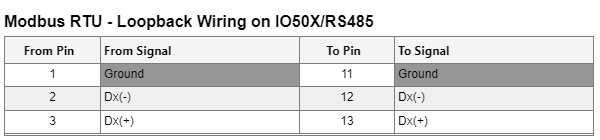

If you use an IO503 or IO505, the wiring represents the connection from channel 1 to channel 2. 

If you are using an IO504, the wiring represents the connection from channel 1 to channel 3.

If you have an IO581, just interconnect two channels with the D-Sub9 cable and adapt the serial Setup block mask accordingly.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_ModbusRTU_1CLI3SRV';
open_system(modelName);

## Selecting the Serial I/O Module

Modbus RTU communicates over plug-in serial I/O modules. The parameter to choose the I/O module type is highlighted with the following command.

 
% Configure the serial module present in your target machine
speedgoat.model.highlight([modelName '/IO5xx_Setup'],'Parameter','parModuleType', 'Open', true);

## Check the UART Settings

To be able to communicate with external devices, the UART settings have to match; to adjust these settings follow the highlighted parameter tab.

 
% Be sure to align the settings to your application
speedgoat.model.highlight([modelName '/IO5xx_Setup'],'Parameter',{'parDataBits1','parParity1','parStopBits1'}, 'Open', true);

The Modbus Organization defined the following settings as Modbus RTU standard which can be modified on Speedgoat serial I/O modules:

- Data bits: 8

- Parity Check: Even

- Stop Bit: 1

## Configure the Modbus RTU Client

 
% Be sure to configure the previously selected serial I/O module
speedgoat.model.highlight([modelName '/Client/ModbusRTU_Client_Setup '], 'Open', true);

Blocks on the client side:

- [Modbus RTU Client Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_client_setup)

- [Modbus RTU Client Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_client_receive)

- [Modbus RTU Client Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_client_send)

The Receive and Send blocks are used to send requests to remote Modbus RTU servers. The Send blocks send write requests with function codes 5, 6, 15, and 16. The Receive blocks send read requests with function codes 1, 2, 3, and 4.

## Configure the Modbus RTU Server

 
% Be sure to configure the previously selected serial I/O module
speedgoat.model.highlight([modelName '/Server/ModbusRTU_Server_Setup '], 'Open', true);

Blocks on the server side:

- [Modbus RTU Server Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_server_setup)

- [Modbus RTU Server Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_server_read)

- [Modbus RTU Server Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mbrtu_server_write)

The Setup block defines the number of nodes that will be emulated and the data table dimensions of each node. The Read and Write blocks are used to access the local Modbus RTU server data tables. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName)  % this will create the real-time application file (.mldatx)

% To compile just one of the subsystems
% slbuild([modelName '/Client']);
% slbuild([modelName '/Server']);

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName)

% Start the real-time application and open the SDI-Viewer
stoptime = 50; % Simulation length [s]
numsignals = 6; % Number of signals to be viewed in the SDI

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;

tg.setStopTime(stoptime);
tg.start;

runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", stoptime, "yMin", -85, "yMax", 85);

The output is then visible in the Simulink Data Inspector (SDI). You should see 6 signal waves, as shown in the image below:

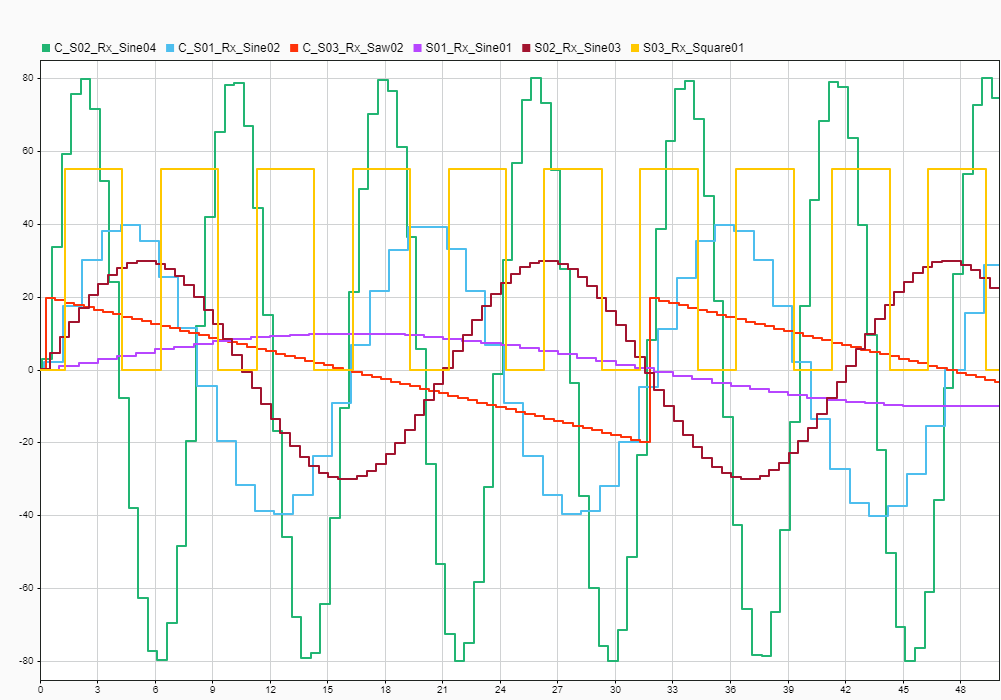

The legend on the top of the diagram helps to identify which signal is which. Running the example model should generate the same signal waves.

## Additional References

- [Modbus RTU Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbrtu_client)

- [Modbus RTU Server documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbrtu_server)